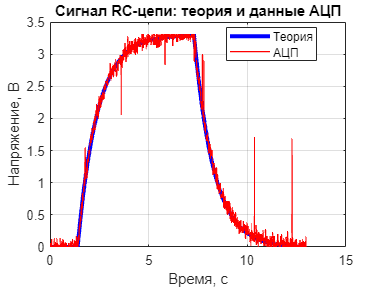

%% 1. Импорт данных
theory   = readtable('theory.csv');
adc      = readtable('adc.csv');
settings = readtable('settings.csv');


% Извлекаем параметры эксперимента
TMeasure    = settings.TMeasure(1);              % общее время, с
Fs          = settings.SamplingFrequency(1);     % частота дискретизации, Гц
VRef        = settings.VRef(1);                  % опорное напряжение, В
Nadc        = settings.Nadc(1);                  % разрядность АЦП

% Число отсчётов и вектор времени
n  = height(adc);
Ts = 1/Fs;
t  = (0:n-1)' * Ts;

x_theory = theory{:, end};

adc_code  = adc{:, end};
x_adc     = adc_code * VRef / (2^Nadc-1);

%% 2. График: теория vs АЦП
figure;
plot(t, x_theory, 'b', 'LineWidth', 3, 'DisplayName', 'Теория');
hold on;
plot(t, x_adc, 'r', 'LineWidth', 1, 'DisplayName', 'АЦП');
xlabel('Время, с');
ylabel('Напряжение, В');
title('Сигнал RC-цепи: теория и данные АЦП');
grid on;
legend('Location','best');


%% 3–4. СКО для исходных данных АЦП
S0_adc = sig_std_dev(x_theory, x_adc);
fprintf('S0 (АЦП) = %.4f В\n', S0_adc);

S0 (АЦП) = 0.0027 В



%% 5–7. Фильтрация
win = 5;   % окно ≤ 10

x_mean   = meanfilt(x_adc, win);          % п.7  — скользящее среднее
x_median = medianfilt(x_adc, win);        % п.8  — скользящая медиана
x_med_mean = meanfilt(x_median, win);     % п.9  — медиана + среднее
x_mean_med = medianfilt(x_mean, win);

S0_mean     = sig_std_dev(x_theory, x_mean);
S0_median   = sig_std_dev(x_theory, x_median);
S0_med_mean = sig_std_dev(x_theory, x_med_mean);
S0_mean_med = sig_std_dev(x_theory, x_mean_med);

fprintf('S0 (среднее)          = %.9f В\n', S0_mean);

S0 (среднее)          = 0.001319925 В


fprintf('S0 (медиана)          = %.9f В\n', S0_median);

S0 (медиана)          = 0.000963333 В


fprintf('S0 (медиана+среднее)  = %.9f В\n', S0_med_mean);

S0 (медиана+среднее)  = 0.000772212 В


fprintf('S0 (среднее+медиана)  = %.9f В\n', S0_med_mean);

S0 (среднее+медиана)  = 0.000772212 В


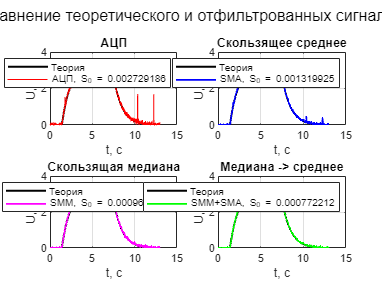


%% 10. Сравнительные графики
figure;
%Данные с ожидаемым откликом и данные с АЦП по времени.
subplot(2,2,1);
plot(t, x_theory, 'k', 'LineWidth', 1.5); hold on;
plot(t, x_adc, 'r');
xlabel('t, с'); ylabel('U, В'); grid on;
title('АЦП');
legend('Теория', sprintf('АЦП, S_0 = %.9f', S0_adc));

%Данные с ожидаемым откликом и данные после фильтра среднего по времени.
subplot(2,2,2);
plot(t, x_theory, 'k', 'LineWidth', 1.5); hold on;
plot(t, x_mean, 'b', 'LineWidth', 1.2);
xlabel('t, с'); ylabel('U, В'); grid on;
title('Скользящее среднее');
legend('Теория', sprintf('SMA, S_0 = %.9f', S0_mean));

%Данные с ожидаемым откликом и данные после фильтра медианы по времени
subplot(2,2,3);
plot(t, x_theory, 'k', 'LineWidth', 1.5); hold on;
plot(t, x_median, 'm', 'LineWidth', 1.2);
xlabel('t, с'); ylabel('U, В'); grid on;
title('Скользящая медиана');
legend('Теория', sprintf('SMM, S_0 = %.9f', S0_median));

%Данные с ожидаемым откликом и данные после фильтра медианы и фильтра среднего (последовательно) по времени
subplot(2,2,4);
plot(t, x_theory, 'k', 'LineWidth', 1.5); hold on;
plot(t, x_med_mean, 'g', 'LineWidth', 1.2);
xlabel('t, с'); ylabel('U, В'); grid on;
title('Медиана -> среднее');
legend('Теория', sprintf('SMM+SMA, S_0 = %.9f', S0_med_mean));

sgtitle('Сравнение теоретического и отфильтрованных сигналов');

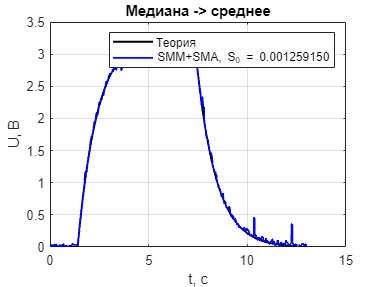



figure;
plot(t, x_theory, 'k', 'LineWidth', 1.5); hold on;
plot(t, x_mean_med, 'b', 'LineWidth', 1.2);
xlabel('t, с'); ylabel('U, В'); grid on;
title('Медиана -> среднее');
legend('Теория', sprintf('SMM+SMA, S_0 = %.9f', S0_mean_med));